data = readtable("../Data/ENB2012_data.xlsx");

Headers = [
    "Relative Compactness"
    "Surface Area"
    "Wall Area"
    "Roof Area"
    "Overall Height"
    "Orientation"
    "Glazing Area"
    "Glazing Area Distribution"
    "Heating Load"
    "Cooling Load"];

data.Properties.VariableNames = Headers;
M = table2array(data);

X = [ones(size(M,1),1), M(:,1:8)];

y = M(:,9);

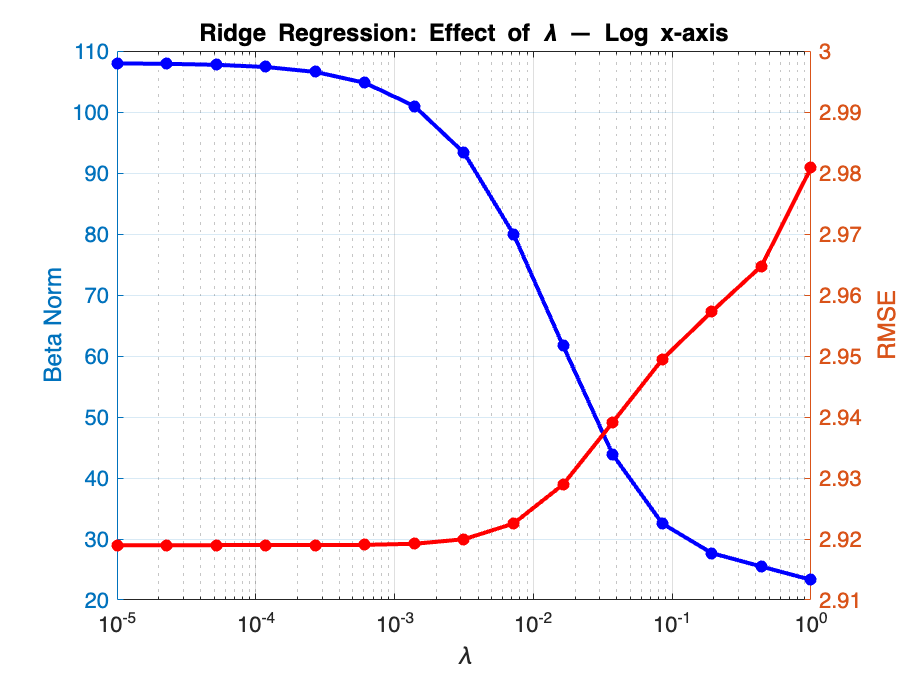

n = 15;
lambda = logspace(-5, 0,n);
RMSE = zeros(n,1);
NormBeta = zeros(n,1);

for i = 1:n
    beta = (X' * X + lambda(i) * eye(9)) \ X' * y;

    RMSE(i) = sqrt(1/length(y) * sum((y - X * beta).^2));
    NormBeta(i) = norm(beta);
end

figure();
yyaxis left
semilogx(lambda, NormBeta, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 4, ...
    'MarkerFaceColor', 'b', ...
    'Color', 'b');
ylabel('Beta Norm', 'FontSize', 11)

yyaxis right
semilogx(lambda, RMSE, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 4, ...
    'MarkerFaceColor', 'r', ...
    'Color', 'r');
ylabel('RMSE', 'FontSize', 11)

grid on
box on
xlabel('\lambda', 'FontSize', 11)
title('Ridge Regression: Effect of \lambda — Log x-axis', ...
    'FontSize', 14, 'FontWeight', 'bold')
set(gca, 'FontSize', 11)

Ridge regression can be analytically implemented and solved for various regularization strengths. It can be seen how the norm of beta can decrease significatively, while the RMSE remains practically constant. For big enough regularization strengths, the RMSE will start to rise.

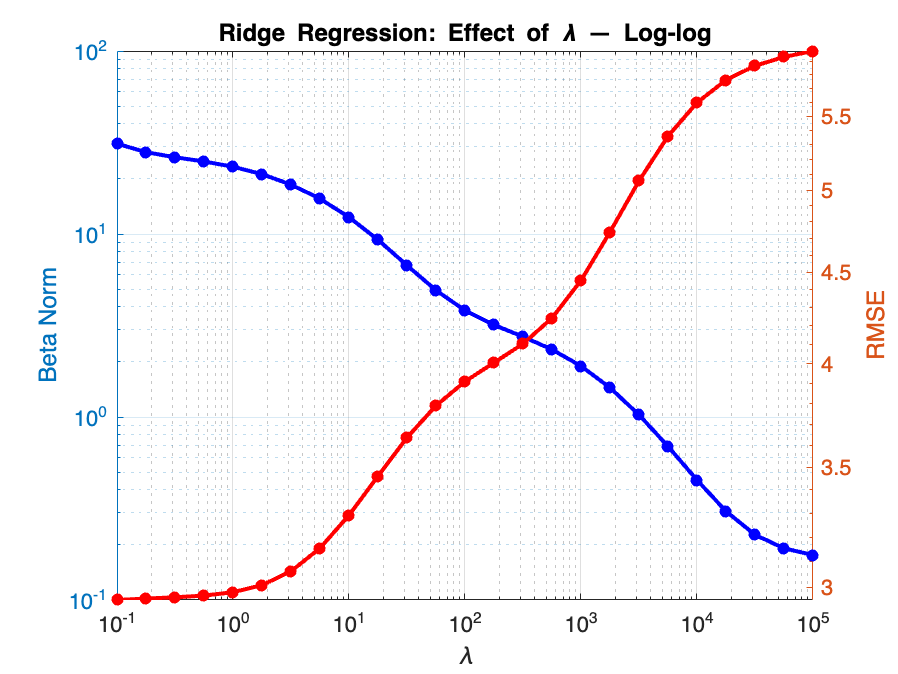

n = 25;
lambda = logspace(-1, 5,n);
RMSE = zeros(n,1);
NormBeta = zeros(n,1);

for i = 1:n
    beta = (X' * X + lambda(i) * eye(9)) \ X' * y;

    RMSE(i) = sqrt(1/length(y) * sum((y - X * beta).^2));
    NormBeta(i) = norm(beta);
end

figure();
yyaxis left
loglog(lambda, NormBeta, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 4, ...
    'MarkerFaceColor', 'b', ...
    'Color', 'b');
ylabel('Beta Norm', 'FontSize', 11)

yyaxis right
loglog(lambda, RMSE, '-o', ...
    'LineWidth', 2, ...
    'MarkerSize', 4, ...
    'MarkerFaceColor', 'r', ...
    'Color', 'r');
ylabel('RMSE', 'FontSize', 11)

grid on
box on
xlabel('\lambda', 'FontSize', 11)
title('Ridge Regression: Effect of \lambda — Log-log', ...
    'FontSize', 14, 'FontWeight', 'bold')
set(gca, 'FontSize', 11)

However, if regularization strength is greatly increased, RMSE will continue to increase with practically exponential correlation with the norm decrease. Thus, simpler models can continue to be obtained, with the correlated increase in fitting error.